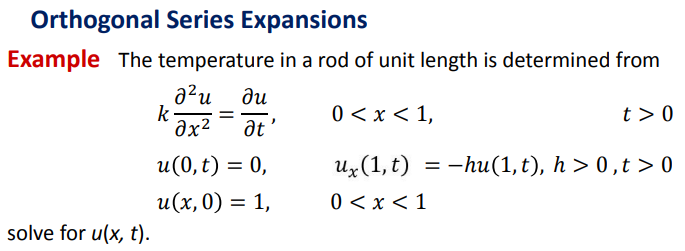

clear
clf
clc
syms x t u(x,t) L D h
assume([L D],"positive")
HeatEq = diff(u,t) == D*diff(u,x,2)

$$HeatEq(x, t) = \frac{\partial }{\partial t}u\left(x,t\right)=\text{D}\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)$$

BC0 = u(0,t) == 0;
syms T(t) X(x)
SepVar = subs(HeatEq,u(x,t),X(x)*T(t));
BCx0 = subs(BC0,u(0,t),X(0))

$$BCx0 = X\left(0\right)=0$$

SepVar = SepVar/(D*X(x)*T(t));
var = children(SepVar);
syms lambda
assume(lambda,"positive")
eqT = var(1) == -lambda^2

$$eqT = \frac{\frac{\partial }{\partial t}T\left(t\right)}{\text{D}\,T\left(t\right)}=-\lambda^{2}$$

eqX = var(2) == -lambda^2

$$eqX = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$

T(t,lambda) = dsolve(eqT)

$$T(t, lambda) = C_{1}\,{\mathrm{e}}^{-\text{D}\,\lambda^{2}\,t}$$

X(x,lambda) = dsolve(eqX,BCx0);
constantX = setdiff(symvar(X(x,lambda)),sym(['C',x,lambda]));
X(x,lambda) = subs(-X(x,lambda),constantX,sym('C2')) 

$$X(x, lambda) = C_{2}\,\sin\left(\lambda \,x\right)$$

DxL(x,lambda) = diff(X,x);
sln = DxL(L,lambda) == -h*X(L,lambda)

$$sln = C_{2}\,\lambda \,\cos\left(L\,\lambda \right)=-C_{2}\,h\,\sin\left(L\,\lambda \right)$$

var = children(sln);
syms b_n ustruct(x,t,n);
T = subs(T(t,lambda),'C1',1)

$$T = {\mathrm{e}}^{-\text{D}\,\lambda^{2}\,t}$$

X = subs(X(x,lambda),'C2',b_n)

$$X = b_{n}\,\sin\left(\lambda \,x\right)$$

ustruct(x,t,n) = X*T

$$ustruct(x, t, n) = b_{n}\,{\mathrm{e}}^{-\text{D}\,\lambda^{2}\,t}\,\sin\left(\lambda \,x\right)$$

lambda = var(2)*lambda/var(1)

$$lambda = -\frac{h\,\sin\left(L\,\lambda \right)}{\cos\left(L\,\lambda \right)}$$

**Plot "tan x = -x" and display"x"**

clf
L = 5

L = 5

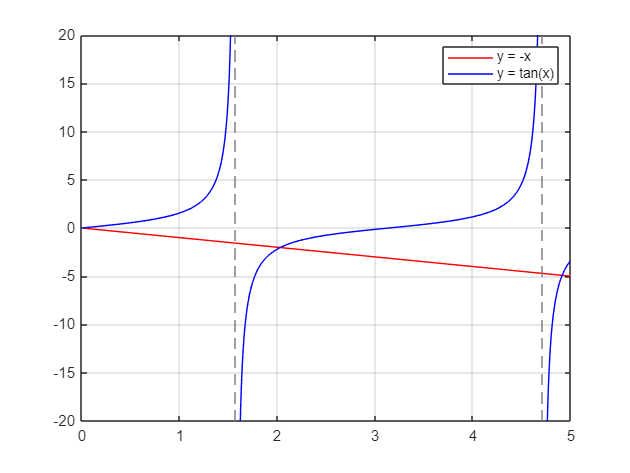

fplot(@(x) -x,[0,L],'r');
grid on, hold on
fplot(@tan,[0,L],'b')
legend('y = -x','y = tan(x)')

x = linspace(0,L);
fun = @(x) tan(x)+x;
f = fun(x);
I = find(sign(f(2:end))-sign(f(1:end-1)));
r = zeros([1 length(I)]);
for n = 1:length(I)
    r(n) = vpa(fzero(fun, x([I(n), I(n)+1])));
end

**Orthogonal Series Expansions**

syms x t n b(n) phi(x)
assume(n,"integer")
phi(x) = 1;
ft0 = subs(ustruct(x,0,n),sym(["b_n" "L"]),[1 L])

$$ft0 = \sin\left(\lambda \,x\right)$$

bnum(n) = simplify(int(phi(x)*ft0, x,[0 L]));
bden(n) = simplify(int(ft0^2,x,[0 L]));
[Num, Den] = numden(bnum);
Den = subs(Den, sym("lambda"), lambda);
bnum(n) = subs(Num/Den, sym("L"),L);
[Num, Den] = numden(bden);
Den = subs(Den, sym("lambda"), lambda);
bden(n) = subs(Num/Den,sym("L"),L);
D = 1

D = 1

Solution = subs(ustruct,"D",D)

$$Solution(x, t, n) = b_{n}\,{\mathrm{e}}^{-\lambda^{2}\,t}\,\sin\left(\lambda \,x\right)$$

b(n) = simplify(bnum/bden)

$$b(n) = -\frac{4\,\left(\cos\left(5\,\lambda \right)-1\right)}{10\,\lambda -\sin\left(10\,\lambda \right)}$$

syms Sigma
heatstructEmb(x,t,n) = [Sigma subs(Solution,sym("b_n"),b)]

$$heatstructEmb(x, t, n) = \left(\begin{array}{cc} \Sigma & -\frac{4\,{\mathrm{e}}^{-\lambda^{2}\,t}\,\sin\left(\lambda \,x\right)\,\left(\cos\left(5\,\lambda \right)-1\right)}{10\,\lambda -\sin\left(10\,\lambda \right)} \end{array}\right)$$

heatstruct(x,t,n) = [Sigma subs(Solution,sym("b_n"),b)]

$$heatstruct(x, t, n) = \left(\begin{array}{cc} \Sigma & -\frac{4\,{\mathrm{e}}^{-\lambda^{2}\,t}\,\sin\left(\lambda \,x\right)\,\left(\cos\left(5\,\lambda \right)-1\right)}{10\,\lambda -\sin\left(10\,\lambda \right)} \end{array}\right)$$

Emb = 0;
heatstructEmb(x,t,n) = subs(Solution,sym("b_n"),b)

$$heatstructEmb(x, t, n) = -\frac{4\,{\mathrm{e}}^{-\lambda^{2}\,t}\,\sin\left(\lambda \,x\right)\,\left(\cos\left(5\,\lambda \right)-1\right)}{10\,\lambda -\sin\left(10\,\lambda \right)}$$

for i = 2:length(I)
    Emb = Emb+subs(heatstructEmb(x,t,n),sym("lambda"),r(i));
end
heatSolN(x,t) = vpa(Emb)

$$heatSolN(x, t) = 0.36327173314057065525947527785641\,{\mathrm{e}}^{-4.1158583656945222804677217095899\,t}\,\sin\left(2.0287578381104340863316792820115\,x\right)+0.084882636315677512410071340465341\,{\mathrm{e}}^{-22.206609902451056892377604749721\,t}\,\sin\left(4.7123889803846898576939650749193\,x\right)+0.012502351192232746072310665776457\,{\mathrm{e}}^{-24.139342030445556848917052805966\,t}\,\sin\left(4.9131804394348836950712211546488\,x\right)+0.25464790894703253723021402139602\,{\mathrm{e}}^{-2.467401100272339654708622749969\,t}\,\sin\left(1.5707963267948966192313216916398\,x\right)$$

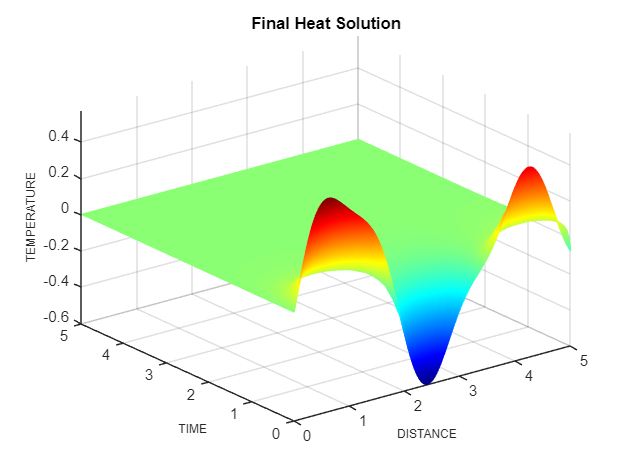

figure
colormap jet
fsurf(heatSolN,[0 L 0 L],"EdgeColor","interp");
title("Final Heat Solution")
xlabel('DISTANCE', 'FontSize',8);
ylabel('TIME','FontSize',8)
zlabel('TEMPERATURE','FontSize',8)

**Heat profile at different times**

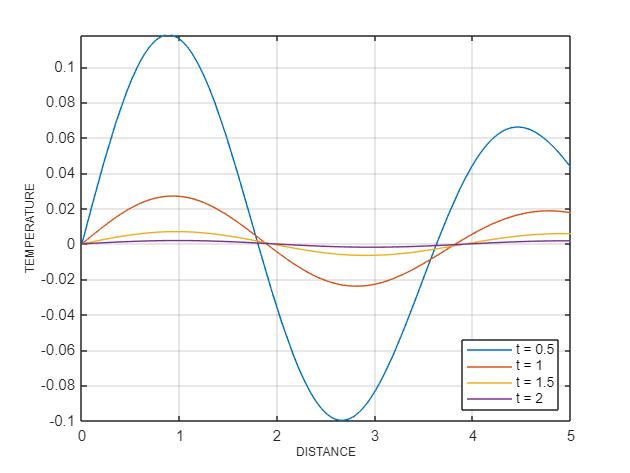

clf
tm = [0.5 1 1.5 2];
for i = 1:length(tm)
    sn = matlabFunction(heatSolN(x, tm(i)));
    fplot(sn, [0 L])
    grid on, hold on
end
xlabel('DISTANCE', 'Fontsize', 8);
ylabel('TEMPERATURE', 'Fontsize', 8);
legend('t = 0.5', 't = 1', 't = 1.5', 't = 2', 'Location', 'southeast')

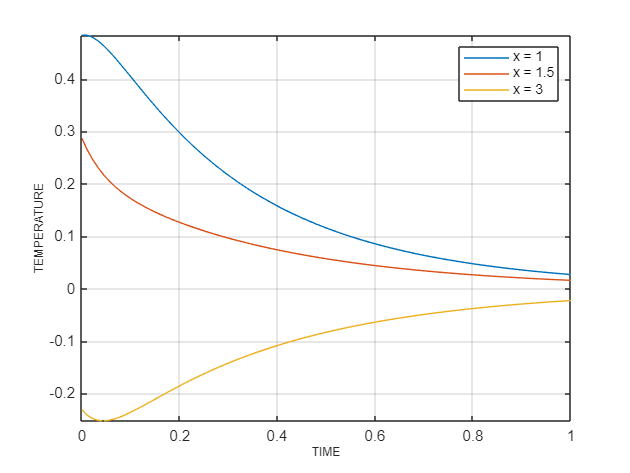

clf
dst = [1 1.5 3];
for i = 1:length(dst)
    sn = matlabFunction(heatSolN(dst(i),t));
    fplot(sn, [0 1])
    grid on,hold on
end
xlabel('TIME','FontSize',8);
ylabel('TEMPERATURE','FontSize',8)
legend('x = 1','x = 1.5','x = 3','Location','northeast')

**Heat profile at various distances**